load concreteIntensityFeatures.mat

concreteTableTest = extractConcreteFeatures(dsTest)

concreteTableTest = 200×4 table
     label        imgName      intensityAvg    intensitySTD
    ________    ___________    ____________    ____________

    No Crack    "00045.jpg"      0.68332         0.030218  
    No Crack    "00313.jpg"      0.62155          0.03279  
    No Crack    "00547.jpg"      0.67598         0.026524  
    No Crack    "00669.jpg"      0.84011         0.015438  
    No Crack    "00998.jpg"      0.66534         0.022601  
    No Crack    "01095.jpg"      0.75242         0.060154  
    No Crack    "01110.jpg"      0.74773         0.023737  
    No Crack    "01311.jpg"      0.83324         0.028074  
    No Crack    "01358.jpg"       0.7357         0.045503  
    No Crack    "01645.jpg"       0.5103          0.03645  
    No Crack    "01662.jpg"      0.71918         0.032597  
    No Crack    "01864.jpg"      0.74156         0.

unlabeledDataLoc = uigetdir();
dsUnlabeledConcrete = imageDatastore(unlabeledDataLoc, "IncludeSubfolders",true, "LabelSource","foldernames");

concreteTableUnlabeled = extractConcreteFeatures(dsUnlabeledConcrete);

% making prediction from the exported model 
concreteTableUnlabeled.Prediction = concreteCrackClassifier.predictFcn(concreteTableUnlabeled)

concreteTableUnlabeled = 10×5 table
          label                imgName         intensityAvg    intensitySTD    Prediction
    __________________    _________________    ____________    ____________    __________

    Unlabeled Concrete    "Concrete_01.JPG"      0.63753         0.080235       Crack    
    Unlabeled Concrete    "Concrete_02.JPG"      0.64298         0.047085       No Crack 
    Unlabeled Concrete    "Concrete_03.JPG"      0.75704         0.038011       No Crack 
    Unlabeled Concrete    "Concrete_04.JPG"      0.61691         0.083861       Crack    
    Unlabeled Concrete    "Concrete_05.JPG"      0.53104         0.023639       No Crack 
    Unlabeled Concrete    "Concrete_06.JPG"      0.65584          0.11181       Crack    
    Unlabeled Concrete    "Concrete_07.JPG"       0.7543         0.059445

Checking the output visually 

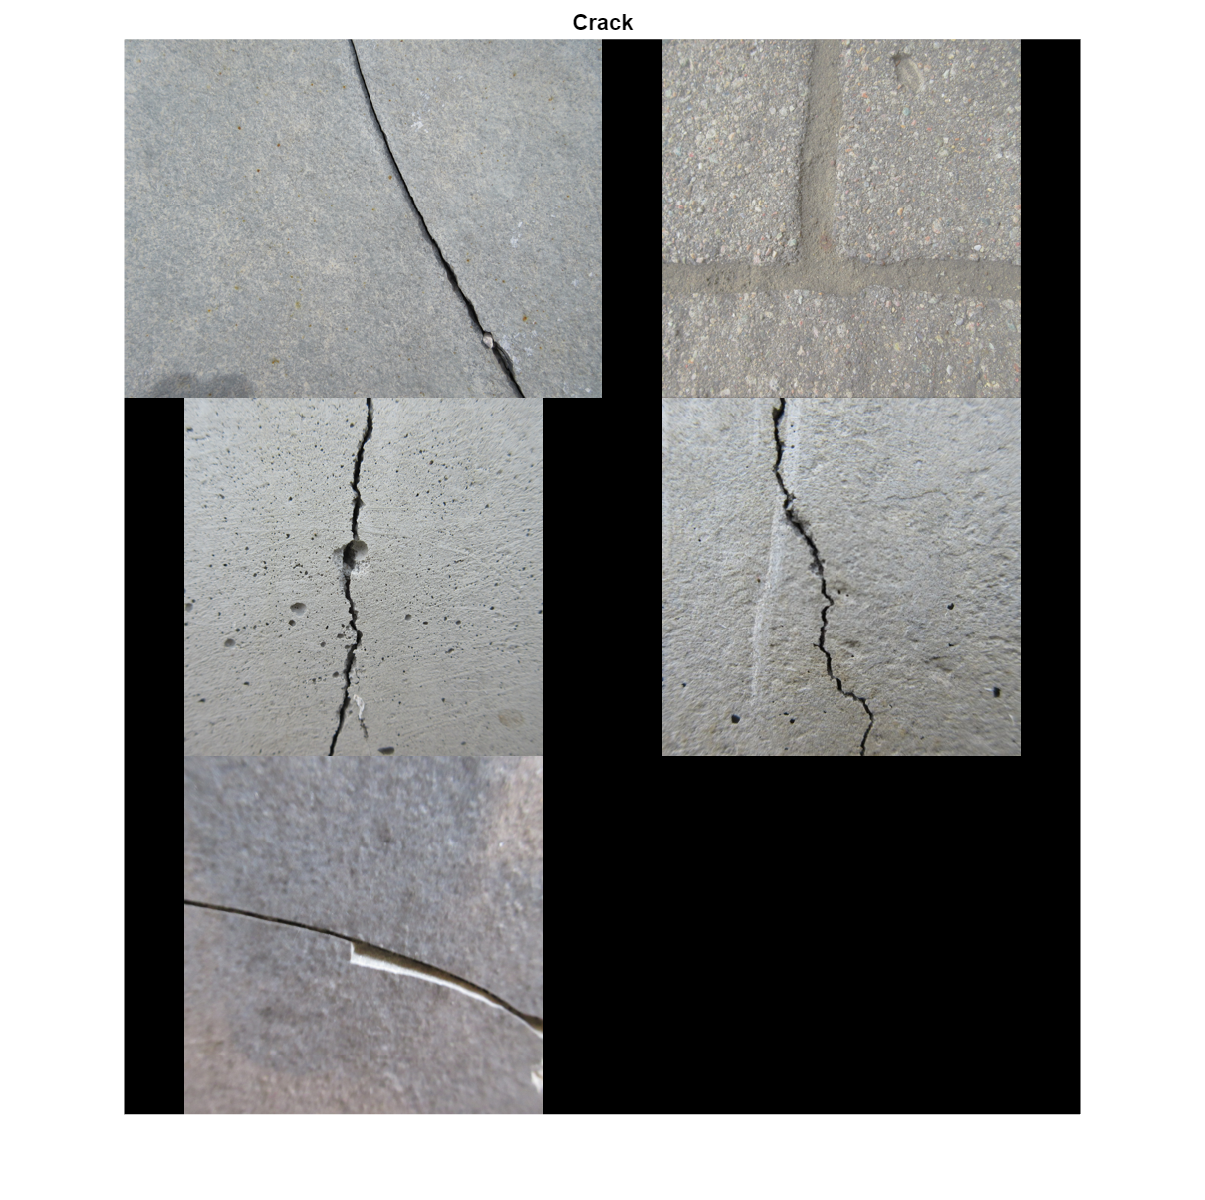

montage(concreteTableUnlabeled.imgName(concreteTableUnlabeled.Prediction == "Crack"))
title("Crack")

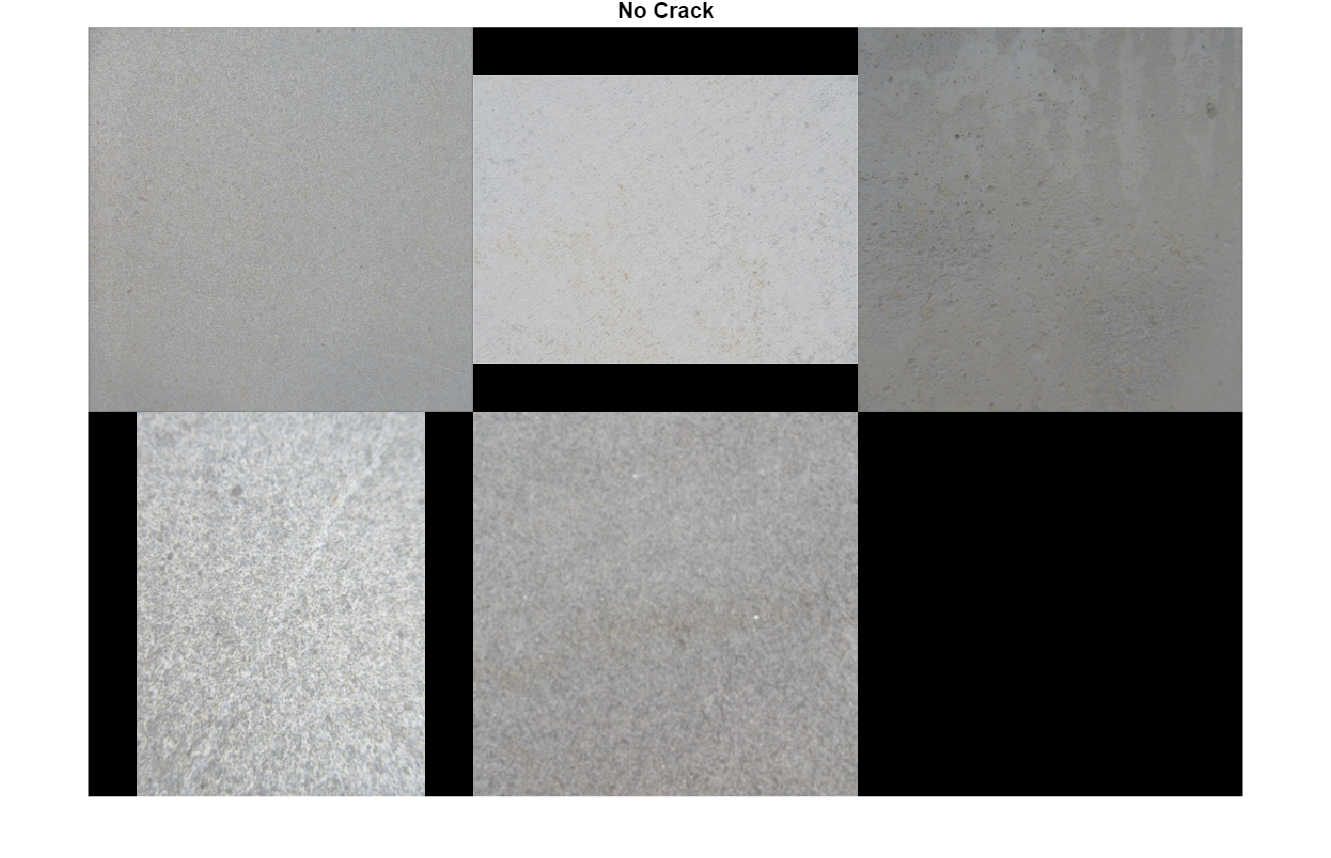

montage(concreteTableUnlabeled.imgName(concreteTableUnlabeled.Prediction == "No Crack"))
title("No Crack")